# Fit of baseline and phase corrected data EDMR-on-chip

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';

## Import

cw = load([Opt.LFolder, '\cwEDMR_chip.mat']);
x = cw.x + 1.2748; y = cw.y/10;
[~, ncw] = size(x); ncw = ncw - 1; % Vbias = 1.6V is not c onsidered;
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\\Data analysis Elexsys';
el = load([Opt.LFolder, '\fit_2021_06_28.mat']);

hh

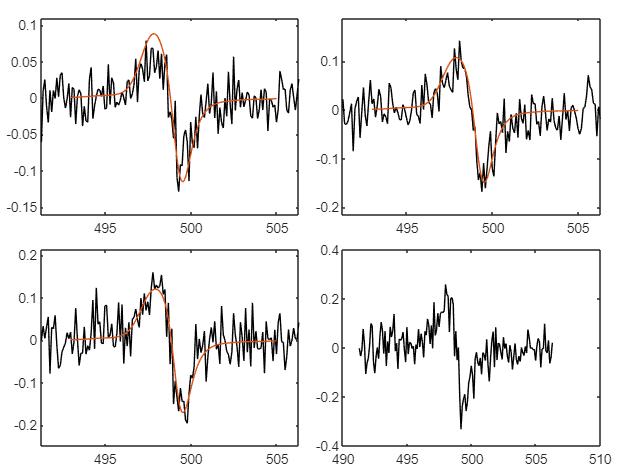

ans = 1.6872e-10

DIOverIpp = 1.6384e-06

SNR = 9.9164

ans = 1.6872e-10

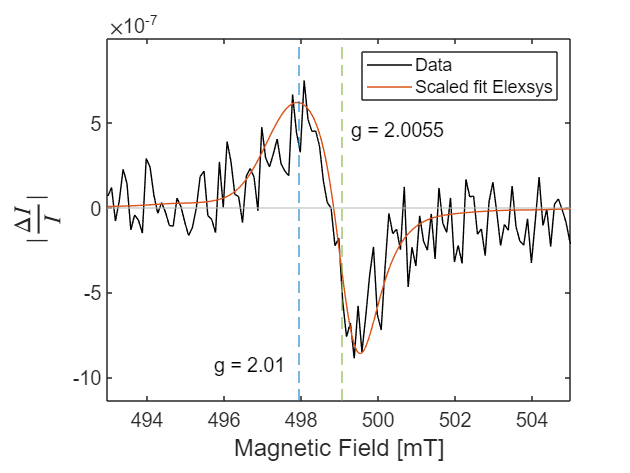

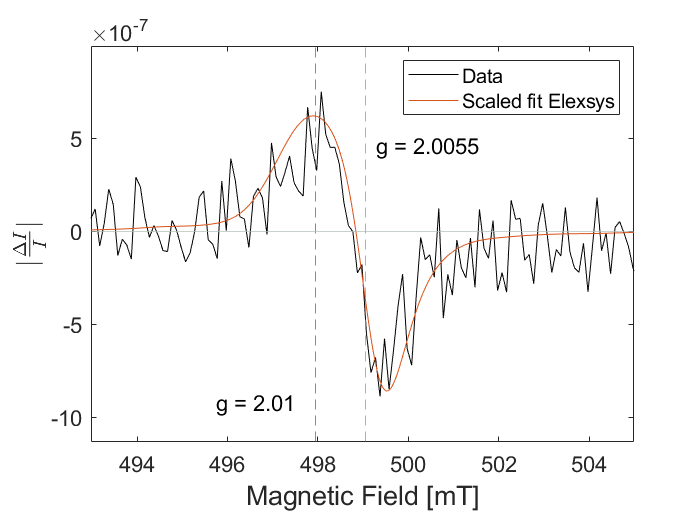

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    nexttile
    plot(x(:, icw), y(:, icw), 'Color', 'black')
    hold on
    propFactor = 0.15;
    if icw < 3
        plot(el.x(:, icw) + 156.85, propFactor*el.Fit(icw).fit)
    elseif icw == 3
        plot(el.x(:, icw + 1) + 156.85, propFactor*el.Fit(icw + 1).fit); % el 4 is at Vbias 1.3V
    elseif icw == 4
        continue;
    end
    xlim(setAxLim(x(:, icw), 0));
    ylim(setAxLim(y(:, icw), 0.15)); 
end


% exportFig(gcf, Opt.SFolder, sprintf('_fit chip m%i', M_PAR), "pdf");
% exportFig(gcf, Opt.SFolder, sprintf('_fit chip m%i', M_PAR), "png");

# 2gFit

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';

## Import

cw = load([Opt.LFolder, '\cwEDMR_chip.mat']);
x = cw.x + 1.2748; y = cw.y/10;
[~, ncw] = size(x); ncw = ncw - 1; % Vbias = 1.6V is not considered;
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys';
el = load([Opt.LFolder, '\fit_2021_06_28_gdoppio.mat']);

figure()
tL = tiledlayout('flow');
Idc = [177 225 280 341 382]*1e-6;
y_ = auToDIOverI(y(:, 2), Idc(2), 1.2e6);

ans = 1.6872e-10

DIOverIpp = getPeakToPeakAmp(x(:, 2), y_)

DIOverIpp = 1.6384e-06

SNR = getSNR(x(:, 2), y_,  [0, 495; 501, 600])

SNR = 9.9164

greenC = '#77AC30';
firstC = '#0072BD';
grayC = '#b2beb5';
for icw = 2:2
    nexttile
    elx = el.x(:, icw) + ...
        mhz2mt(14 - el.Fit(icw).argsfit{1, 2}.mwFreq, 2.0055)*1000 + 0.3;
    Idc = [177 225 280 341 382]*1e-6;
    y_ = auToDIOverI(y(:, icw), Idc(icw), 1.2e6);
    h(1) = plot(x(:, icw), y_, 'Color', 'black');
    hold on
    propFactor = DIOverIpp/58e-6;
    IdcE = str2double(el.cwStruct(icw).Title(end-4:end-2))*1e-6;
    conversion = 1/15e4*1e-3/IdcE;
    yE = propFactor*conversion*el.Fit(icw).fit;
    h(2) = plot(elx, yE);
    h(3) = xline(mhz2mt(14*1000, 2.0057) + 0.3, '--', 'Color', greenC);
    h(4) = xline(mhz2mt(14*1000, 2.009)+ 0.3, '--', 'Color', firstC);
    h(5) = yline(0, 'Color', grayC);
        Label3 = "g = 2.0057";
text(0.525, 0.7, Label3, 'Units', 'normalized', ...
    'FontSize', 13);
Label4 = "g = 2.009";
text(0.24, 0.1, Label4, 'Units', 'normalized', ...
    'FontSize', 13);
    xlim(setAxLim(elx, 0));
    ylim(setAxLim(y_, 0.15));
    xticks(495:2.5:504)
end

ans = 1.6872e-10

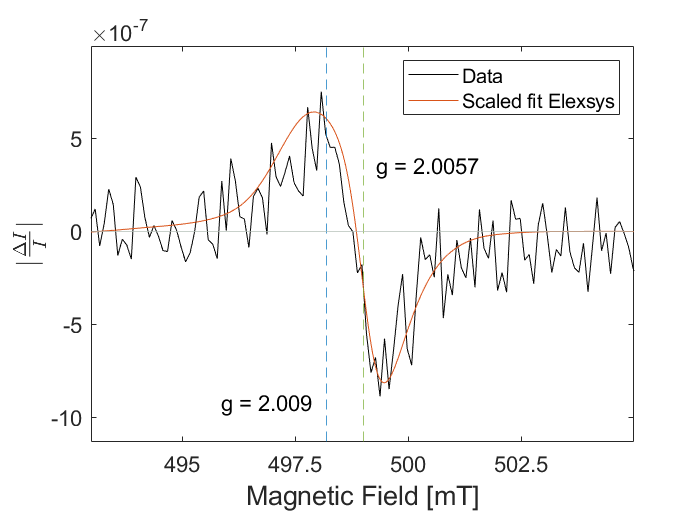

lgd = legendFirstTile(tL, ["Data", "Scaled fit Elexsys"]);
lgd.Location = "northeast";
labelAxesFig(tL, "Magnetic Field [mT]", '$| \frac{\Delta I}{I} |$')
exportFig(gcf, Opt.SFolder, '_cwEDMR 2gFit chip Vbias 1p2', '.png')

# Fit gVBT

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';

## Import

cw = load([Opt.LFolder, '\cwEDMR_chip.mat']);
x = cw.x + 1.2748; y = cw.y/10;
[~, ncw] = size(x); ncw = ncw - 1; % Vbias = 1.6V is not considered;
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys';
el = load([Opt.LFolder, '\fit_2021_06_28_gVBT.mat']);

figure()
tL = tiledlayout('flow');
Idc = [177 225 280 341 382]*1e-6;
y_ = auToDIOverI(y(:, 2), Idc(2), 1.2e6);

ans = 1.6872e-10

DIOverIpp = getPeakToPeakAmp(x(:, 2), y_)

DIOverIpp = 1.6384e-06

SNR = getSNR(x(:, 2), y_,  [0, 495; 501, 600])

SNR = 9.9164

greenC = '#77AC30';
firstC = '#0072BD';
grayC = '#b2beb5';
for icw = 2:2
    nexttile
    elx = el.x(:, icw) + ...
        mhz2mt(14 - el.Fit(icw).argsfit{1, 2}.mwFreq, 2.0055)*1000 + 0.3;
    Idc = [177 225 280 341 382]*1e-6;
    y_ = auToDIOverI(y(:, icw), Idc(icw), 1.2e6);
    h(1) = plot(x(:, icw), y_, 'Color', 'black');
    hold on
    propFactor = DIOverIpp/58e-6;
    IdcE = str2double(el.cwStruct(icw).Title(end-4:end-2))*1e-6;
    conversion = 1/15e4*1e-3/IdcE;
    yE = propFactor*conversion*el.Fit(icw).fit;
    h(2) = plot(elx, yE);
    h(3) = xline(mhz2mt(14*1000, 2.0055) + 0.3, '--', 'Color', greenC);
    h(4) = xline(mhz2mt(14*1000, 2.0089)+ 0.3, '--', 'Color', firstC);
    h(5) = yline(0, 'Color', grayC);
        Label3 = "g = 2.0055";
text(0.525, 0.7, Label3, 'Units', 'normalized', ...
    'FontSize', 13);
Label4 = "g = 2.0089";
text(0.225, 0.1, Label4, 'Units', 'normalized', ...
    'FontSize', 13);
    xlim(setAxLim(elx, 0));
    ylim(setAxLim(y_, 0.15));
    xticks(495:2.5:504)
end

ans = 1.6872e-10

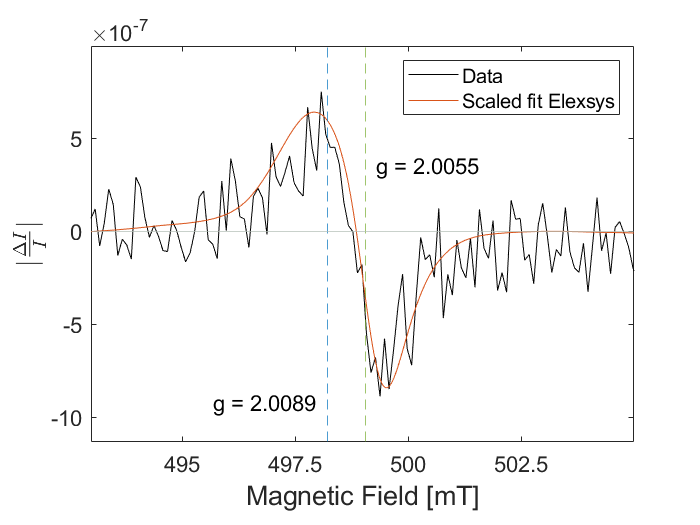

lgd = legendFirstTile(tL, ["Data", "Scaled fit Elexsys"]);
lgd.Location = "northeast";
labelAxesFig(tL, "Magnetic Field [mT]", '$| \frac{\Delta I}{I} |$')
exportFig(gcf, Opt.SFolder, '_cwEDMR gVBT fit chip Vbias 1p2', '.png')

# Fit with fixed g values

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';

## Import

cw = load([Opt.LFolder, '\cwEDMR_chip.mat']);
x = cw.x + 1.2748; y = cw.y/10;
[~, ncw] = size(x); ncw = ncw - 1; % Vbias = 1.6V is not considered;
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys';
el = load([Opt.LFolder, '\fit_2021_06_28.mat']);


figure()
tL = tiledlayout('flow');
Idc = [177 225 280 341 382]*1e-6;
y_ = auToDIOverI(y(:, 2), Idc(2), 1.2e6);

ans = 1.6872e-10

DIOverIpp = getPeakToPeakAmp(x(:, 2), y_)

DIOverIpp = 1.6384e-06

SNR = getSNR(x(:, 2), y_,  [0, 495; 501, 600])

SNR = 9.9164

greenC = '#77AC30';
firstC = '#0072BD';
grayC = '#b2beb5';
for icw = 2:2
    nexttile
    elx = el.x(:, icw) + ...
        mhz2mt(14 - el.Fit(icw).argsfit{1, 2}.mwFreq, 2.0055)*1000 + 0.3;
    Idc = [177 225 280 341 382]*1e-6;
    y_ = auToDIOverI(y(:, icw), Idc(icw), 1.2e6);
    h(1) = plot(x(:, icw), y_, 'Color', 'black');
    hold on
    propFactor = DIOverIpp/58e-6;
    IdcE = str2double(el.cwStruct(icw).Title(end-4:end-2))*1e-6;
    conversion = 1/15e4*1e-3/IdcE;
    yE = propFactor*conversion*el.Fit(icw).fit;
    h(2) = plot(elx, yE);
    h(3) = xline(mhz2mt(14*1000, 2.0055) + 0.3, '--', 'Color', greenC);
    h(4) = xline(mhz2mt(14*1000, 2.01)+ 0.3, '--', 'Color', firstC);
    h(5) = yline(0, 'Color', grayC);
        Label3 = "g = 2.0055";
text(0.525, 0.7, Label3, 'Units', 'normalized', ...
    'FontSize', 13);
Label4 = "g = 2.01";
text(0.225, 0.1, Label4, 'Units', 'normalized', ...
    'FontSize', 13);
    xlim(setAxLim(elx, 0));
    ylim(setAxLim(y_, 0.15));
    xticks(495:2.5:504)
end

ans = 1.6872e-10

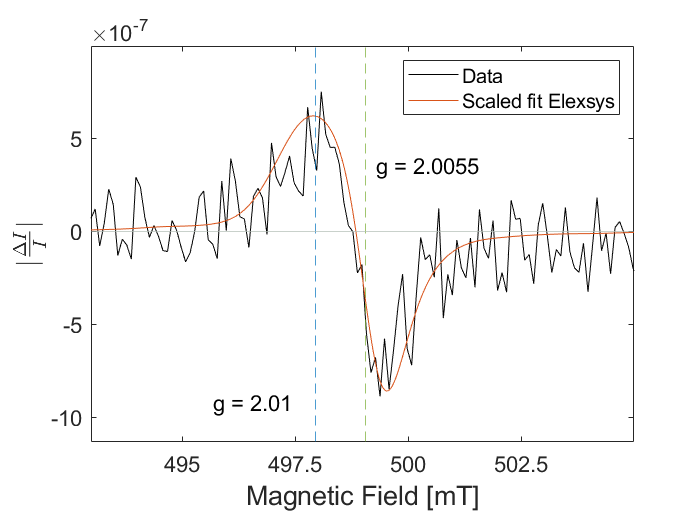

lgd = legendFirstTile(tL, ["Data", "Scaled fit Elexsys"]);
lgd.Location = "northeast";
labelAxesFig(tL, "Magnetic Field [mT]", '$| \frac{\Delta I}{I} |$')
exportFig(gcf, Opt.SFolder, '_cwEDMR fixed g chip Vbias 1p2', '.png')

function y = auToDIOverI(y, I0, ampFactor)
    % 1000 because lockin is in mV and not in V
    % 0.7 is the RMS factor
    % ampFactor should be in Ohm = V/A
    y = y/(1000*0.7*ampFactor); % A
    max(y)
    y = y./I0; % I0 should be in A
end